%% Load set of data
filenames1 = {'03-10-2016_21_08_31_top'
'03-10-2016_21_07_39_top'
'03-10-2016_21_06_48_top'
'03-10-2016_21_05_56_top'
'03-10-2016_21_05_04_top'
'03-10-2016_21_04_13_top'
'03-10-2016_21_03_20_top'
'03-10-2016_21_00_27_top'
'03-10-2016_20_59_36_top'
'03-10-2016_20_58_44_top'
'03-10-2016_20_57_52_top'
'03-10-2016_20_57_00_top'
'03-10-2016_20_56_09_top'
'03-10-2016_20_55_17_top'
'03-10-2016_20_45_26_top'
'03-10-2016_20_42_51_top'
'03-10-2016_20_41_59_top'
'03-10-2016_20_41_08_top'
'03-10-2016_20_40_15_top'
'03-10-2016_20_39_24_top'}; 
imagepowers1 = [0.850000000000000
1.10000000000000
0.700000000000000
0.750000000000000
0.600000000000000
0.900000000000000
0.550000000000000
0.900000000000000
1.05000000000000
0.800000000000000
0.600000000000000
0.750000000000000
1.10000000000000
0.950000000000000
0.700000000000000
0.800000000000000
1
0.650000000000000
1.05000000000000
0.600000000000000];

% Using
filenames  = filenames1;
imagepowers = imagepowers1;
datasetname = 'mar10-imaging-intensity-calibration.mat';

%% Importing data
% Settings
sett.crop = {'rect',268,217,170,300};
sett.bg = {'none',20};
sett.Nsat = Inf;
sett.pol = {'sub',0.05};

% % Test few images to make sure for crop region, etc.
% temp = imagedata(filenames{2},'plot',{1},'crop',sett.crop,'bg',sett.bg,'Nsat',sett.Nsat);
% % Fields needed from temp - filepath, imagetype, od2, wa2, woa2, bgavg

% Import all data
d = struct([]);
for i = 1:length(filenames)
    temp = imagedata(filenames{i},'plot',{0},'crop',sett.crop,'bg',sett.bg,'Nsat',sett.Nsat,'pol',sett.pol);
    d(i).od = temp.od2;
    d(i).wa = temp.wa2;
    d(i).woa = temp.woa2;
    d(i).filename = temp.filename;
    d(i).imagetype = temp.imagetype;
%     d(i).bg = temp.bgavg;
    d(i).impower = imagepowers(i);
end

d1 = d;
save(datasetname,'d1','sett');



%% Go through all pixels (averaging 10 along rows for better s2n)

% Define range and averaging
ys = (110:1:180)';            % All Y pixels with atoms
xs = (75:1:110);   % Edges for the X averaging
% dxs = xs(2) - xs(1) - 1;    % # of pixels in each averaging bin
ys = (10:2:280)';
xs = (77:2:117);

% Initialize empty variables
alpha_all = zeros(length(ys) * (length(xs)-1), 1);
ODreal_all = zeros(length(ys) * (length(xs)-1), 1);
xbins = length(xs)-1;
ybins = length(ys)-1;

% Process each bin
for i = 1:ybins
    for j = 1:xbins
        tODc = arrayfun(@(x) mean(mean(x.od( ys(i)+1:ys(i+1),xs(j)+1:xs(j+1)) )),d,'UniformOutput',true);
        tDI = arrayfun(@(x) mean(mean(x.woa(  ys(i)+1:ys(i+1)    ,xs(j)+1:xs(j+1)) - x.wa(ys(i)+1:ys(i+1),xs(j)+1:xs(j+1)))),d,'UniformOutput',true);
        [talpha,tODreal] = fitline_saturation_intensity_2(tODc,tDI,'plot',{0});
        alpha_all((i-1)*xbins + j) = talpha;
        ODreal_all((i-1)*xbins + j) = tODreal;
    end
end

% Save variables
res.info = 'March 10 2016 dataset 1 results (tests).';
res.alpha_all = alpha_all;
res.ODreal_all = ODreal_all;


% Bin
binlen = 10;
alpha_bin = zeros(fix(length(alpha_all)/binlen),1);
ODreal_bin = zeros(fix(length(alpha_all)/binlen),1);

[tODreal_all,sortindex] = sort(ODreal_all);
talpha_all = alpha_all(sortindex);

j = 0;
for i = 1:binlen:length(alpha_all)-binlen
    j = j + 1;
    alpha_bin(j) = mean(talpha_all(i:i+binlen));
    ODreal_bin(j) = mean(tODreal_all(i:i+binlen));
end

% Save variables
res.alpha_bin = alpha_bin;
res.ODreal_bin = ODreal_bin;

% Save to file
res1 = res;
save(datasetname,'res1','-append');
clearvars i j xbins ybins tODc tDI talpha tODreal


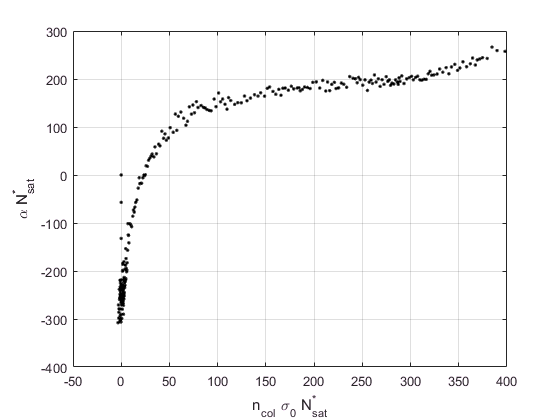

%% Plots
figure;
plot(res.ODreal_bin,res.alpha_bin,'k.');
xlabel('n_{col} \sigma_0 N_{sat}^*'); %xlim([0 500]);
ylabel('\alpha N_{sat}^*'); %ylim([0 500]);
grid on;

% title('Fudge (\alpha) as a function of density, assuming constant \beta, from hybrid box.');
% text(600,300,'\alpha log(I_i / I_f) + (I_i-I_f) / N_{sat}^* = n_{col} \sigma_0');
% text(600,200,'N_{sat}^{*} is effective saturation count.');
% text(600,100,'\alpha is density dependent fudge.');

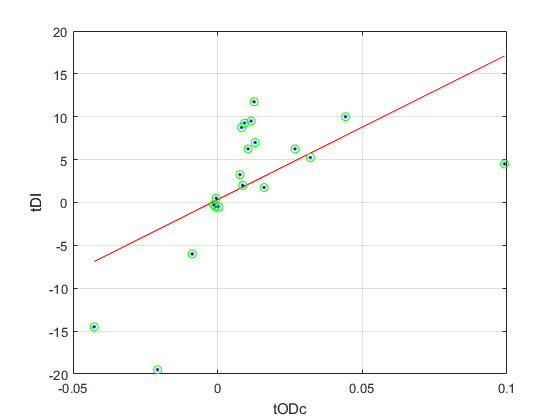

%% Tests
i = fix((length(ys)-1)*rand(1)); 
j = fix((length(xs)-1)*rand(1));
% 
% i = 1;
% j = 10;

tODc = arrayfun(@(x) mean(mean(x.od( ys(i)+1:ys(i+1),xs(j)+1:xs(j+1)) )),d,'UniformOutput',true);
tDI = arrayfun(@(x) mean(mean(x.woa(  ys(i)+1:ys(i+1)    ,xs(j)+1:xs(j+1)) - x.wa(ys(i)+1:ys(i+1),xs(j)+1:xs(j+1)))),d,'UniformOutput',true);
[talpha,tODreal] = fitline_saturation_intensity_2(tODc,tDI,'plot',{1});